clear; close all; clc;
addpath('functions');
addpath('visualization');
addpath('output');

% toggles
sweepHDM = true;
debug    = false;

Nx = 75;    % x spacial grid res
Ny = 75;    % y spacial grid res

% nonlinearity constants
alpha =0.03; % K^-1
T_ref = 300;                        % K

% parameter domain D = [0, 0.5] x [5e-3, 0.025] x [0.4, 0.6]
pts = 10; % discretization

% grid initialization
dx = 1 / (Nx-1);
dy = 1 / (Ny-1);
N  = Nx * Ny;

x_values = linspace(0, 1, Nx);
y_values  = linspace(0, 1, Ny);

% enforcing Dirichlet profile (x = 0)
T_D = @(y, y_bar) (300      .* (y < 1/3) ...
                + (300 + 325 * (sin(3 * pi * abs(y - y_bar)) + 1)) .* (y >= 1/3 & y <= 2/3) ...
                + (300      .* (y > 2/3)));

## Part 1: Computing the Candidate Parameter Points

rng(53);
disp("Building parameter domain...")

Building parameter domain...



U     = linspace(0.1,  0.6,   pts);
kappa = linspace(2e-3, 0.025, pts);
y_bar = linspace(0.4,  0.6,   pts);

[P1, P2, P3] = ndgrid(U, kappa, y_bar);
mu = [P1(:), P2(:), P3(:)];
N_mu = size(mu, 1);
disp("Done.")

Done.



if sweepHDM
    fprintf('==================================================================\n');
    fprintf('Part 1: Computing Candidate Parameter Points\n');
    fprintf('==================================================================\n');
    disp("Recomputing HDM solutions for ROM construction.")

    fprintf("Number of candidate parameters: %d\n", N_mu);
    
    if debug
        disp("First 10 parameter triples for inspection:")
        disp(mu(1:min(10, N_mu), :))
    end

    disp("Computing and storing solutions...")

    nx_int = Nx - 2;
    ny_int = Ny - 2;
    nDOF   = nx_int * ny_int;

    w         = zeros(nDOF, N_mu);
    iters_all = zeros(N_mu, 1);
    res_all   = zeros(N_mu, 1);
    failed    = false(N_mu, 1);

    epsilon = 1e-6;
    max_iter = 200;

    tic;
    t_last_print = -inf;
    k_last_print = -inf;
    for k = 1:N_mu
        mu_k = mu(k, :);
        [w(:,k), iters_all(k), residual] = computeNonLinearHDM(Nx, Ny, dx, dy, T_D, y_values, mu_k, alpha, T_ref, epsilon, max_iter);
        res_all(k) = residual(end);
        failed(k)  = residual(end) >= 1e-6;

        t_now = toc;
        if (mod(k, 100) == 0)
            fprintf('  %4d / %4d  (%5.1f s elapsed)  failures so far: %3d\n', ...
                k, N_mu, t_now, sum(failed(1:k)));
            t_last_print = t_now;
            k_last_print = k;
        end
    end
    time_HDM = toc;

    fprintf('HDM construction time: %.4f seconds\n', time_HDM);
    fprintf('Converged: %d / %d\n', N_mu - sum(failed), N_mu);

    save('output/mu_nonlinear.mat',   'mu');
    save('output/w_nonlinear.mat',    'w', '-v7.3');
    save('output/meta_nonlinear.mat', 'time_HDM', 'iters_all', 'res_all', 'failed', 'alpha', 'T_ref');
end

Part 1: Computing Candidate Parameter Points


Recomputing HDM solutions for ROM construction.


Number of candidate parameters: 1000


Computing and storing solutions...


   100 / 1000  ( 11.9 s elapsed)  failures so far:   0
   200 / 1000  ( 24.0 s elapsed)  failures so far:   0
   300 / 1000  ( 35.9 s elapsed)  failures so far:   0
   400 / 1000  ( 47.9 s elapsed)  failures so far:   0
   500 / 1000  ( 59.9 s elapsed)  failures so far:   0
   600 / 1000  ( 72.1 s elapsed)  failures so far:   0
   700 / 1000  ( 84.2 s elapsed)  failures so far:   0
   800 / 1000  ( 96.0 s elapsed)  failures so far:   0
   900 / 1000  (108.5 s elapsed)  failures so far:   0
  1000 / 1000  (121.0 s elapsed)  failures so far:   0


HDM construction time: 120.9912 seconds


Converged: 1000 / 1000




load('mu_nonlinear.mat');
load('w_nonlinear.mat');
if exist('meta_nonlinear.mat', 'file')
    load('meta_nonlinear.mat');
else
    time_HDM = NaN;
end

t_hdm_per_solve = time_HDM / N_mu;   % avg HDM cost per solve
fprintf('HDM cost per solve: %.4f s\n', t_hdm_per_solve);

HDM cost per solve: 0.1210 s


## Part 2: Buidling Linear PROM Using Random (Latin Hypercube) Sampling of Snapshots

A snapshot budget sweep is conducted to demonstrate the weak Kolmogorov barrier specific to this sytem (inability of any linear subspace to accurately approximate the solution manifold at affordable dimension). 

This motivates the nonlinear ROM strategies that follow Part 2.

fprintf('==================================================================\n');

fprintf('Part 2: Linear PROM — Snapshot Budget Sweep\n');

Part 2: Linear PROM — Snapshot Budget Sweep


fprintf('==================================================================\n');


N_mu   = size(mu, 1);
nx_int = Nx - 2;
ny_int = Ny - 2;
N_int  = nx_int * ny_int;

fprintf('\n%-6s  %-12s  %-12s  %-12s  %-12s  %-10s\n', ...
    'k', 'E_avg', 'E_max', 't_offline(s)', 't_online(s)', 'rcond');


k       E_avg         E_max         t_offline(s)  t_online(s)   rcond     



e_avg_hist = nan(50, 1);
e_max_hist = nan(50, 1);
k_plateau  = NaN;

rng(42);
for k_test = 1:50

    % draw k_test LHS snapshots
    lhs_k    = lhsdesign(k_test, 3);
    U_k      = 0.1  + lhs_k(:,1) * (0.6   - 0.1);
    kappa_k  = 5e-3 + lhs_k(:,2) * (0.025 - 5e-3);
    y_bar_k  = 0.4  + lhs_k(:,3) * (0.6   - 0.4);
    mu_lhs_k = [U_k, kappa_k, y_bar_k];

    % snap to nearest grid point + build basis
    w_lhs_k   = zeros(N_int, k_test);
    idx_lhs_k = zeros(k_test, 1);
    tic;
    for j = 1:k_test
        [~, idx_min] = min(vecnorm(mu - mu_lhs_k(j,:), 2, 2));
        idx_lhs_k(j) = idx_min;
        w_lhs_k(:,j) = w(:, idx_min);
    end
    V_k = buildBasisPOD(w_lhs_k, false);
    t_basis = toc;

    % total offline = HDM solves + basis construction
    t_offline_k = k_test * t_hdm_per_solve + t_basis;

    % check condition of reduced operator
    [A_check, ~] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu(1,:));
    A_r_check    = V_k' * A_check * V_k;
    rc           = rcond(A_r_check);

    if rc < 1e-12
        fprintf('%-6d  SINGULAR (rcond = %.2e) — stopping\n', k_test, rc);
        k_plateau = k_test - 1;
        break;
    end

    % test set
    idx_test_k = setdiff(1:N_mu, idx_lhs_k);
    mu_test_k  = mu(idx_test_k, :);
    w_test_k   = w(:, idx_test_k);

    % online evaluation
    w_r_k = zeros(N_int, length(idx_test_k));
    tic;
    for j = 1:length(idx_test_k)
        [A_k, b_k]     = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_test_k(j,:));
        [A_r_k, b_r_k] = assembleROM(A_k, b_k, V_k);
        w_r_k(:,j)     = computeROM(A_r_k, b_r_k, V_k);
    end
    t_online_k = toc;

    errs               = computeErrors(w_test_k, w_r_k);
    e_avg_hist(k_test) = mean(errs);
    e_max_hist(k_test) = max(errs);

    fprintf('%-6d  %-12.4f  %-12.4f  %-12.4f  %-12.4f  %-10.2e\n', ...
        k_test, e_avg_hist(k_test), e_max_hist(k_test), t_offline_k, t_online_k, rc);
end

1       0.0554        0.2343        0.1220        0.2918        1.00e+00  
2       0.0466        0.2295        0.2446        0.2946        6.48e-02  
3       0.0438        0.2250        0.3634        0.2846        4.42e-02  
4       0.0500        0.1551        0.4863        0.2721        3.35e-02  
5       0.1220        0.3877        0.6073        0.4584        1.85e-02  
6       0.1917        0.6488        0.7266        0.3182        6.80e-03  
7       0.1387        0.2225        0.8477        0.3374        8.14e-03  
8       0.1870        0.4883        0.9687        0.3698        3.95e-03  
9       0.1299        0.1919        1.0901        0.3843        4.05e-03  
10      0.1333        0.2102        1.2119        0.3983        3.85e-03  
11      0.1282        0.1911        1.3336        0.4066        3.53e-03  
12      0.1294        0.1936        1.4536        0.4467        3.22e-03  
13      0.1280        0.1932        1.5739        0.4357        2.24e-03  
14      0.1439        0.2

24      SINGULAR (rcond = 1.03e-15) — stopping


k_plateau = 15

% record timing and errors at saturation k
lhs_k    = lhsdesign(k_plateau, 3);
U_k      = 0.1  + lhs_k(:,1) * (0.6   - 0.1);
kappa_k  = 5e-3 + lhs_k(:,2) * (0.025 - 5e-3);
y_bar_k  = 0.4  + lhs_k(:,3) * (0.6   - 0.4);
mu_lhs_k = [U_k, kappa_k, y_bar_k];

w_lhs_k   = zeros(N_int, k_plateau);
idx_lhs_k = zeros(k_plateau, 1);

tic;
for j = 1:k_plateau
    [~, idx_min] = min(vecnorm(mu - mu_lhs_k(j,:), 2, 2));
    idx_lhs_k(j) = idx_min;
    w_lhs_k(:,j) = w(:, idx_min);
end

V = buildBasisPOD(w_lhs_k, false);
t_offline_affine = toc + (k_plateau * t_hdm_per_solve);

idx_test = setdiff(1:N_mu, idx_lhs_k);
mu_test  = mu(idx_test, :);
w_test   = w(:, idx_test);

w_r = zeros(N_int, length(idx_test));
tic;
for j = 1:length(idx_test)
    [A, b]     = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_test(j,:));
    [A_r, b_r] = assembleROM(A, b, V);
    w_r(:,j)   = computeROM(A_r, b_r, V);
end
t_online_affine = toc;

errors_affine = computeErrors(w_test, w_r);
E_max_affine  = max(errors_affine);
E_avg_affine  = mean(errors_affine);
E_std_affine  = std(errors_affine);

fprintf('\n==================================================================\n');

fprintf('Linear PROM at saturation (k = %d snapshots):\n', k_plateau);

Linear PROM at saturation (k = 15 snapshots):


fprintf('E_avg        = %.4f ± %.4f\n', E_avg_affine, E_std_affine);

E_avg        = 0.1450 ± 0.0630


fprintf('E_max        = %.4f\n', E_max_affine);

E_max        = 0.2496


fprintf('t_offline    = %.4f s\n', t_offline_affine);

t_offline    = 1.8175 s


fprintf('t_online     = %.4f s\n', t_online_affine);

t_online     = 0.4770 s


fprintf('==================================================================\n');

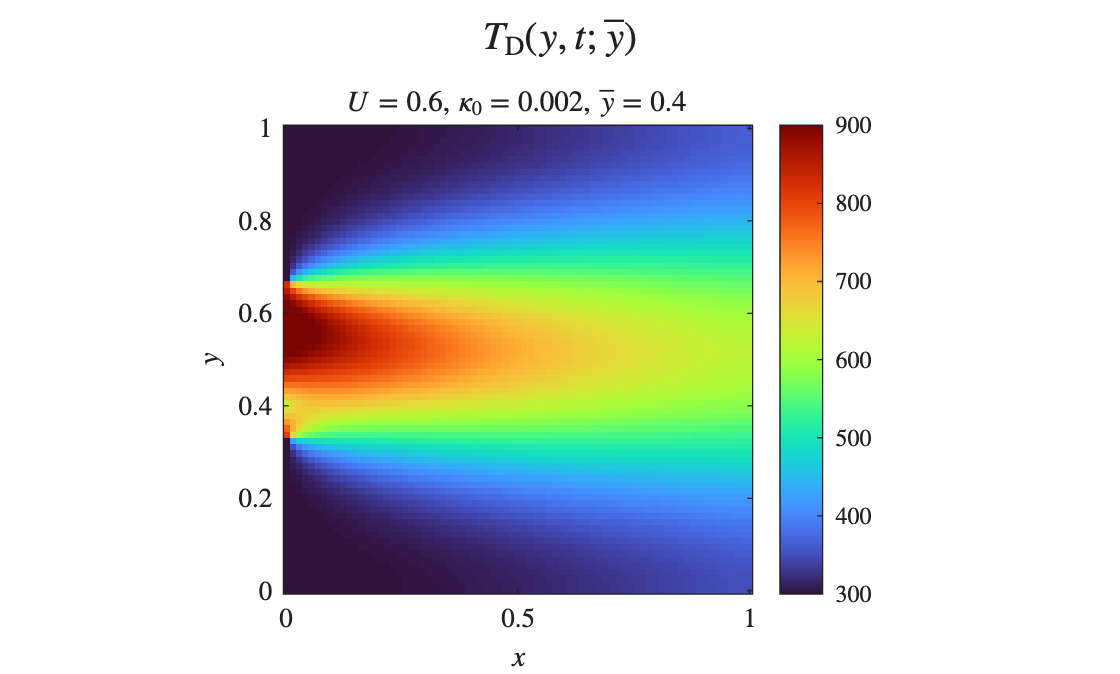


% visualize one test case
j_vis = 10;
T_hdm = reshapeSolution(w_test(:,j_vis),     Nx, Ny, T_D, y_values, mu_test(j_vis,:));
T_rom = reshapeSolution(w_r(:,j_vis),        Nx, Ny, T_D, y_values, mu_test(j_vis,:));
plotSolution(T_hdm,          mu_test(j_vis,:), false);

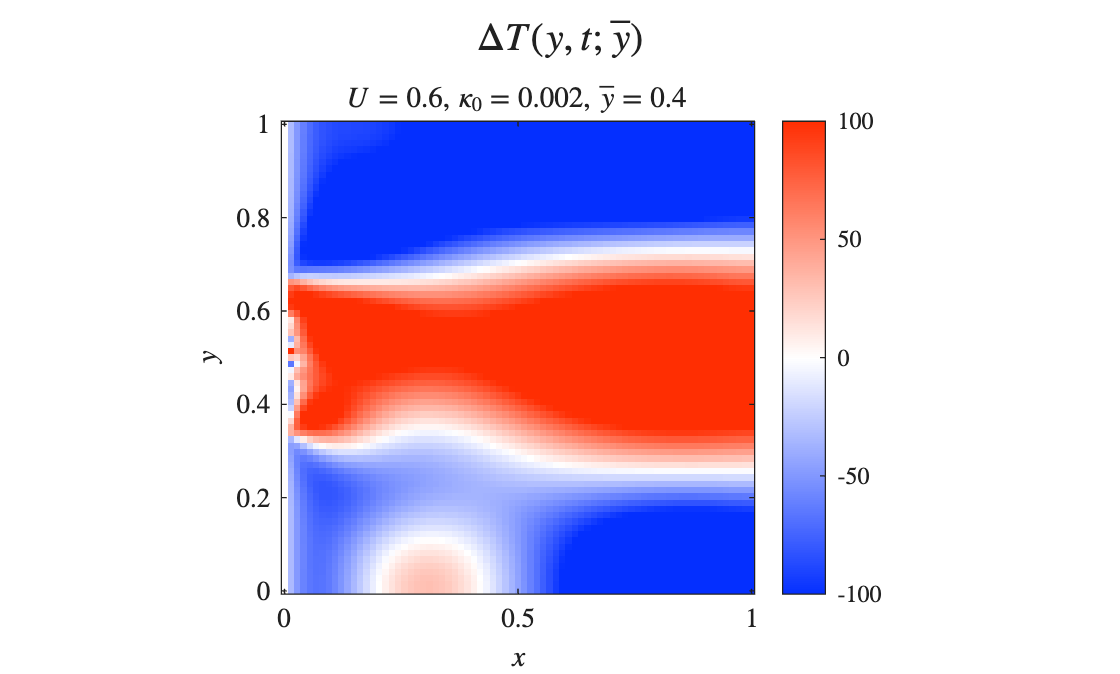

plotSolution(T_rom - T_hdm,  mu_test(j_vis,:), true);

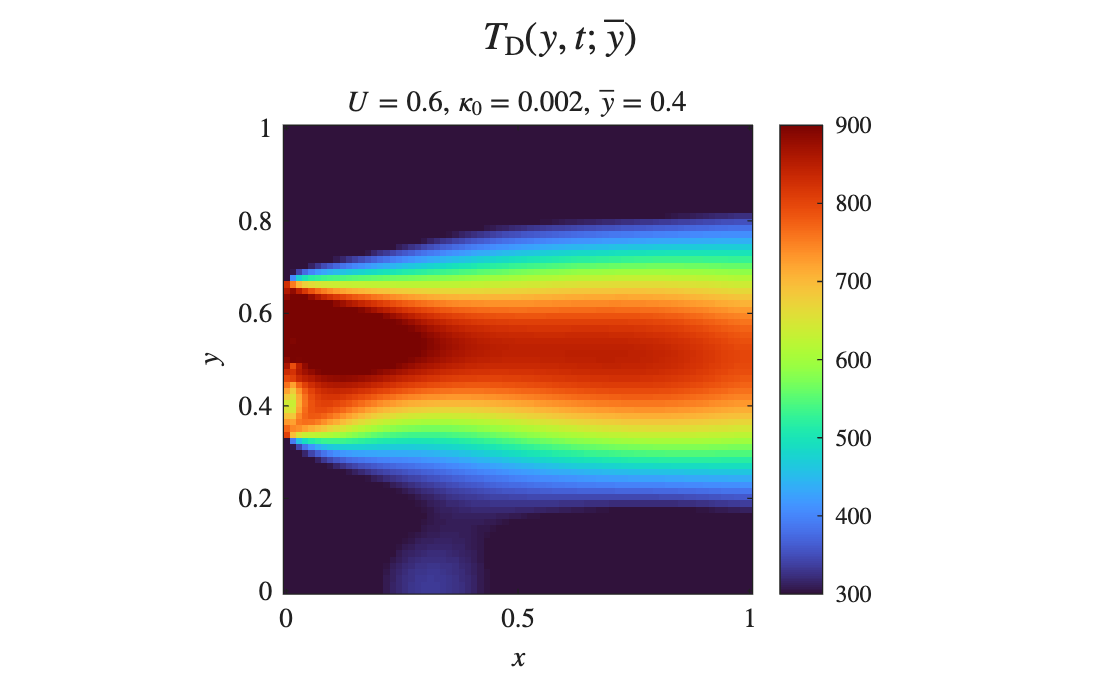

plotSolution(T_rom,          mu_test(j_vis,:), false);

## Part 3: DEIM Hyperreduction of Non-Linear Diffusivity

% params
k_deim  = 10;    % new snapshot basis (independent from Part 2)
k_f     = 4;     % upper limit of DEIM POD modes

N_snap = k_deim;

param_bounds = [0.1,   0.6;
                2e-3,  0.025;
                0.4,   0.6];

[w_lhs, idx_lhs, idx_test, mu_test, w_test_deim] = sampleLHS(w, mu, k_deim, param_bounds, 42);

fprintf('==================================================================\n');

fprintf('Part 3: DEIM Hyperreduction\n');

Part 3: DEIM Hyperreduction


fprintf('==================================================================\n');


% collecting nonlinear (kappa) snapshots
fprintf('Collecting nonlinear kappa snapshots...\n');


nx_int = Nx - 2;
ny_int = Ny - 2;
N_int  = nx_int * ny_int;

k_prim_diem = k_deim - k_f;
tic;
f_snap = zeros(N_int, k_prim_diem);
for k = 1:k_prim_diem
    f_snap(:, k) = computeNonLinearKappa(w(:,k), mu(k,2), alpha, T_ref);
end

%% build DEIM basis V_f
epsilon_deim = 1e-4;
V_f = buildBasisPOD(f_snap, debug);


ROB V built using POD with size [5329 x 6] = [N x N_snapshots].
Checking if V'V = I...Success!
___________________________________________________________________

V_f = V_f(:, 1:k_f);

% run greedy alg
[P, I_deim] = buildMaskDEIM(V_f, debug);


DEIM interpolation indices selected: k_f = 4
Indices: 42 1718 4929 2920 
condition number of P'*V_f: 2.24e+00
P'*V_f is well-conditioned.



% DEIM projection operator (1 or 0)
Pi_f = V_f / (P' * V_f);   % N_int x k_f

% precomputed linear operator and BC vector
%  (these don't depend on kappa so they never change across Picard iters)
[A_lin, b_lin] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, [mu(1,1), 1.0, mu(1,3)]);
% kappa = 1 placeholder 

% reuse same LHS training/test split from part 2 (final iter)
% recall idx_test and mu_test already defined from Part 2
N_test   = length(idx_test);
w_r_deim = zeros(N_int, N_test);

k_rom    = size(V, 2);
A_r_conv = zeros(k_rom, k_rom, N_test);
A_r_diff = zeros(k_rom, k_rom, N_test);
b_r_conv = zeros(k_rom, N_test);
b_r_diff = zeros(k_rom, N_test);

for j = 1:N_test
    mu_j = mu_test(j,:);
    [A_d, b_d] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, [mu_j(1), 1.0, mu_j(3)]);
    [A_c, b_c] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, [mu_j(1), 0.0, mu_j(3)]);
    A_r_conv(:,:,j) = V' * A_c * V;
    A_r_diff(:,:,j) = V' * (A_d - A_c) * V;
    b_r_conv(:,j)   = V' * b_c;
    b_r_diff(:,j)   = V' * (b_d - b_c);
end
t_offline_deim = toc + (k_deim * t_hdm_per_solve);

% print statements moved out of timer
fprintf('Nonlinear snapshots collected: [%d x %d]\n', size(f_snap,1), size(f_snap,2));

Nonlinear snapshots collected: [5329 x 6]


fprintf('kappa range across all snapshots: [%.4f, %.4f]\n', min(f_snap(:)), max(f_snap(:)));

kappa range across all snapshots: [0.0020, 0.0401]



fprintf('\nBuilding DEIM basis V_f...\n');


Building DEIM basis V_f...


fprintf('DEIM basis size: k_f = %d\n', k_f);

DEIM basis size: k_f = 4



fprintf('\nRunning greedy DEIM algorithm...\n');


Running greedy DEIM algorithm...


fprintf('DEIM indices selected: %s\n', mat2str(I_deim'));

DEIM indices selected: [42 1718 4929 2920]



fprintf('DEIM offline completed in %.4f seconds.\n', t_offline_deim);

DEIM offline completed in 2.1655 seconds.


fprintf('Pi_f size: [%d x %d]\n', size(Pi_f,1), size(Pi_f,2));

Pi_f size: [5329 x 4]


fprintf('\nEvaluating DEIM-HPROM on test parameter set...\n');


Evaluating DEIM-HPROM on test parameter set...


tic;
for j = 1:N_test
    if mod(j, 100) == 0
        fprintf('  %4d / %4d\n', j, N_test);
    end

    mu_j     = mu_test(j,:);
    kappa0_j = mu_j(2);

    % warm start: no assembly
    A_r_base = A_r_conv(:,:,j) + kappa0_j * A_r_diff(:,:,j);
    b_r_base = b_r_conv(:,j)   + kappa0_j * b_r_diff(:,j);
    w_j      = V * -(A_r_base \ b_r_base);

    % DEIM kappa correction
    f         = computeNonLinearKappa(w_j(I_deim), kappa0_j, alpha, T_ref);
    kappa_eff = mean(max(Pi_f * f, kappa0_j * 0.5));

    % corrected solve: no assembly
    A_r_eff       = A_r_conv(:,:,j) + kappa_eff * A_r_diff(:,:,j);
    b_r_eff       = b_r_conv(:,j)   + kappa_eff * b_r_diff(:,j);
    w_r_deim(:,j) = V * -(A_r_eff \ b_r_eff);
end

   100 /  990
   200 /  990
   300 /  990
   400 /  990
   500 /  990
   600 /  990
   700 /  990
   800 /  990
   900 /  990


t_online_deim = toc;

fprintf('DEIM online completed in %.4f seconds for %d test points.\n', t_online_deim, N_test);

DEIM online completed in 0.1727 seconds for 990 test points.



% vis test case
fprintf('Visualizing DEIM-HPROM delta for test point 1...\n');

Visualizing DEIM-HPROM delta for test point 1...


j_vis    = 10;
T_hdm_v  = reshapeSolution(w_test_deim(:,j_vis),      Nx, Ny, T_D, y_values, mu_test(j_vis,:));
T_deim_v = reshapeSolution(w_r_deim(:,j_vis),    Nx, Ny, T_D, y_values, mu_test(j_vis,:));

plotSolution(T_hdm_v,             mu_test(j_vis,:), false);

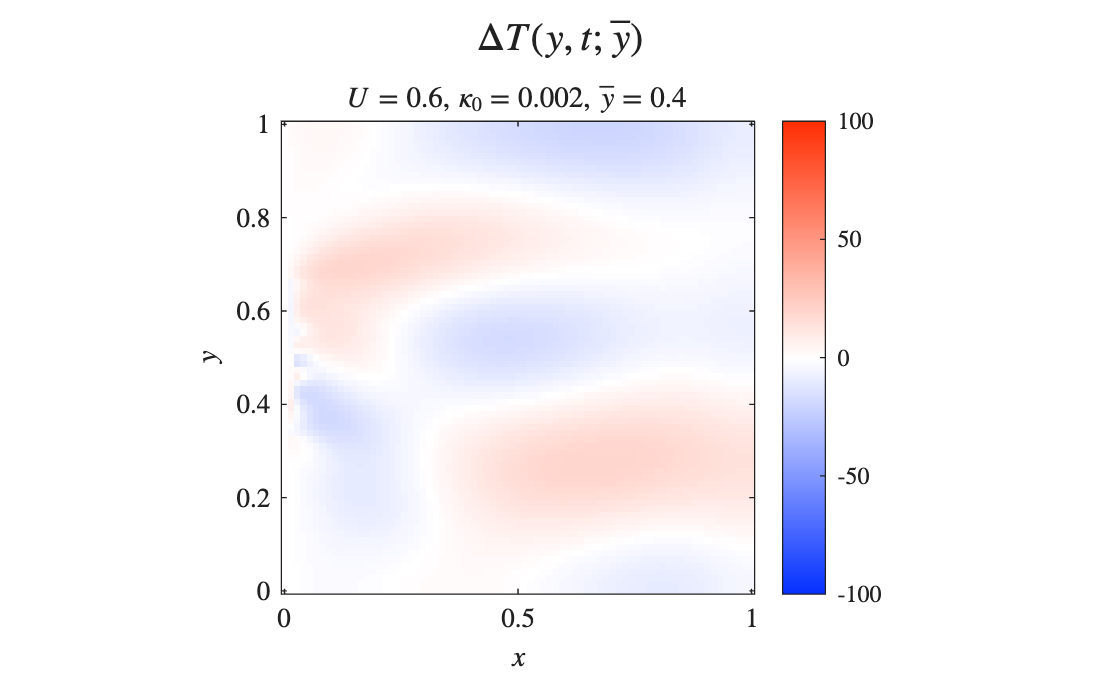

plotSolution(T_deim_v - T_hdm_v,  mu_test(j_vis,:), true);

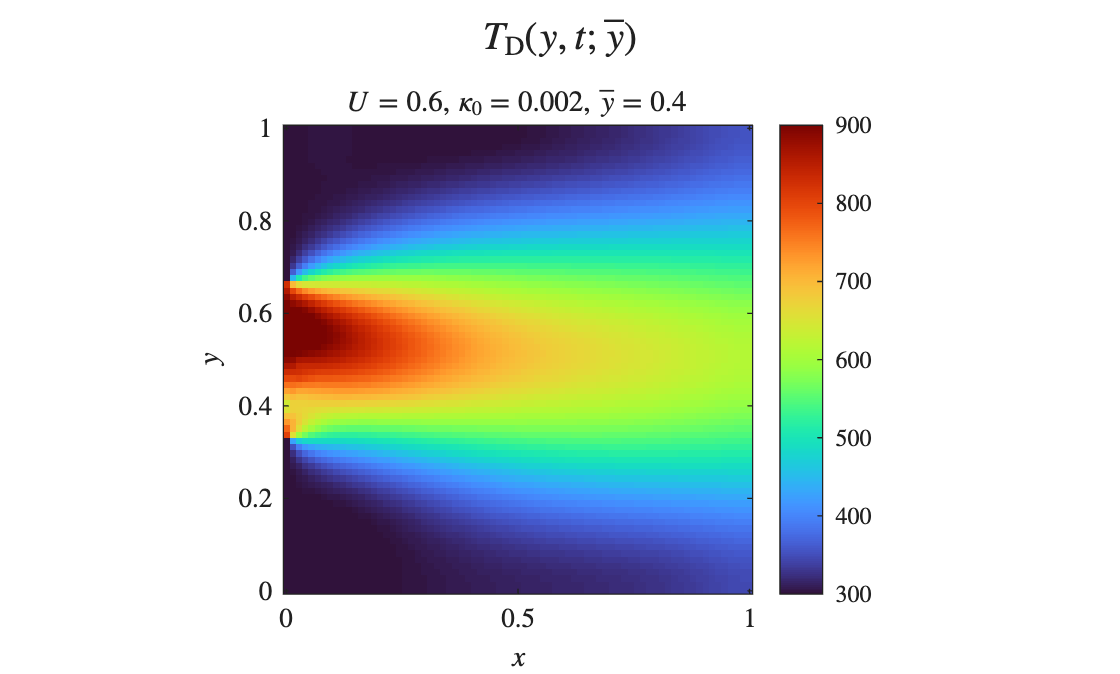

plotSolution(T_deim_v,            mu_test(j_vis,:), false);


% errors
errors_deim = computeErrors(w_test_deim, w_r_deim);
E_max_deim  = max(errors_deim);
E_avg_deim  = mean(errors_deim);

fprintf('\n==================================================================\n');

fprintf('DEIM-HPROM results (%d test points):\n', N_test);

DEIM-HPROM results (990 test points):


fprintf('E_max = %.4f\n', E_max_deim);

E_max = 0.0510


fprintf('E_avg = %.4f\n', E_avg_deim);

E_avg = 0.0115


## Part 4: ANN-Augmented PMOR

The network maps primary reduced coordinates **q **through a single hidden layer of 32 neurons with tanh (∘) activation to secondary closure coordinates.

    

fprintf('==================================================================\n');

fprintf('Part 4: ANN-Augmented PMOR\n');

Part 4: ANN-Augmented PMOR


fprintf('==================================================================\n');


k_ann  = 20;   % independent snapshot budget
[w_lhs_ann, idx_lhs_ann, idx_test_ann, mu_test_ann, w_test_ann_hdm] = ...
    sampleLHS(w, mu, k_ann, param_bounds, 42);

%  following Barnett-Farhat-Maday:
%       construct ROB [V | V_bar] of dimension (k_prim + k_bar) < k_ideal << N
%       split into primary V (for PROM) and secondary V_bar (for ANN closure)
k_prim = 6;                     % primary:   dimension of PROM
k_bar  = k_ann - k_prim;        % secondary: remaining modes

w_ref      = mean(w_lhs_ann, 2);        % centroid of training set
W_centered = w_lhs_ann - w_ref;         % N_int x k_ann

[V_train, S_svd, ~] = svd(W_centered, 'econ');  % N_int x k_ann, orthonormal by construction
lambda_sorted = diag(S_svd).^2;
E_POD_train   = 1 - cumsum(lambda_sorted) / sum(lambda_sorted);

V_prim = V_train(:, 1:k_prim);          % N_int x k_prim  (primary basis)
V_bar  = V_train(:, k_prim+1:end);      % N_int x k_bar   (secondary basis)

% verify orthogonality V'*V_bar = 0
assert(max(abs(V_prim'*V_bar), [], 'all') < 1e-8, 'V and V_bar not orthogonal');
fprintf('V_prim size: [%d x %d]\n', size(V_prim));

V_prim size: [5329 x 6]


fprintf('V_bar  size: [%d x %d]\n', size(V_bar));

V_bar  size: [5329 x 14]


fprintf('Orthogonality check passed.\n');

Orthogonality check passed.



fprintf('\nHonest POD energy from %d training snapshots:\n', k_ann);


Honest POD energy from 20 training snapshots:


fprintf('Mode  |  Cumulative energy  |  Truncation error\n');

Mode  |  Cumulative energy  |  Truncation error


fprintf('------|---------------------|-------------------\n');

------|---------------------|-------------------


for i = 1:length(lambda_sorted)
    fprintf('  %3d |  %.8f       |  %.2e\n', i, 1-E_POD_train(i), E_POD_train(i));
end

    1 |  0.83860186       |  1.61e-01
    2 |  0.96280302       |  3.72e-02
    3 |  0.98536804       |  1.46e-02
    4 |  0.99729545       |  2.70e-03
    5 |  0.99868453       |  1.32e-03
    6 |  0.99938297       |  6.17e-04
    7 |  0.99970112       |  2.99e-04
    8 |  0.99989244       |  1.08e-04
    9 |  0.99994093       |  5.91e-05
   10 |  0.99997305       |  2.69e-05
   11 |  0.99998723       |  1.28e-05
   12 |  0.99999409       |  5.91e-06
   13 |  0.99999751       |  2.49e-06
   14 |  0.99999874       |  1.26e-06
   15 |  0.99999943       |  5.75e-07
   16 |  0.99999990       |  1.01e-07
   17 |  0.99999999       |  1.06e-08
   18 |  1.00000000       |  3.53e-09
   19 |  1.00000000       |  0.00e+00
   20 |  1.00000000       |  0.00e+00


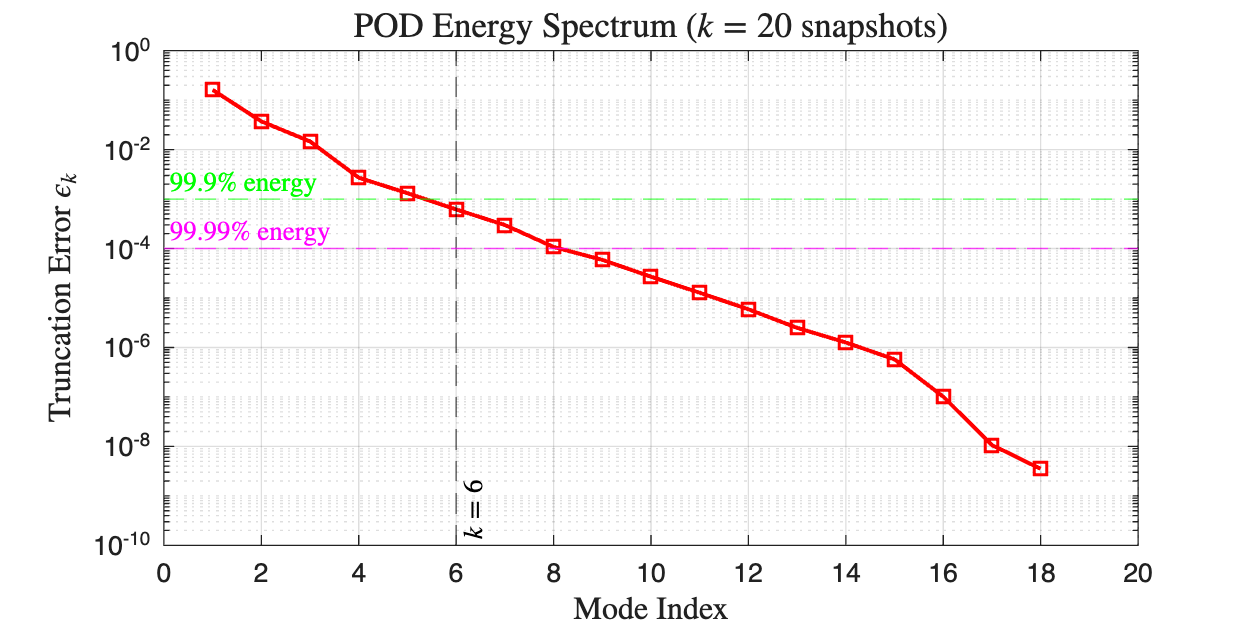


figure('Color','w','Position',[100 100 800 400]);
semilogy(1:length(lambda_sorted), E_POD_train, 'r-s', ...
    'MarkerSize', 6, 'LineWidth', 1.5);
hold on;
xline(k_prim,         'k--', sprintf('$k=%d$',          k_prim),       'Interpreter','latex', 'LabelVerticalAlignment','bottom');
xline(k_prim + k_bar, 'k:',  sprintf('$k+\\bar{k}=%d$', k_prim+k_bar), 'Interpreter','latex', 'LabelVerticalAlignment','bottom');
yline(1e-3, 'g--', '$99.9\%$ energy',   'Interpreter','latex', 'LabelHorizontalAlignment','left');
yline(1e-4, 'm--', '$99.99\%$ energy', 'Interpreter','latex', 'LabelHorizontalAlignment','left');
grid on;
xlabel('Mode Index', 'Interpreter','latex', 'FontSize', 12);
ylabel('Truncation Error $\epsilon_k$', 'Interpreter','latex', 'FontSize', 12);
title(sprintf('POD Energy Spectrum ($k=%d$ snapshots)', k_ann), ...
    'Interpreter','latex', 'FontSize', 13);


%  bases fixed from training only
W_all_centered = w - w_ref;
q_all     = V_prim' * W_all_centered;   % k_prim x N_mu
q_bar_all = V_bar'  * W_all_centered;   % k_bar  x N_mu

% sanity check on training points only
w_recon_tr = w_ref + V_prim * q_all(:,idx_lhs_ann) + V_bar * q_bar_all(:,idx_lhs_ann);
recon_err  = mean(vecnorm(w_lhs_ann - w_recon_tr) ./ vecnorm(w_lhs_ann));
fprintf('Training reconstruction error (V + V_bar): %.2e\n', recon_err);

Training reconstruction error (V + V_bar): 1.19e-16



% train/test split
idx_tr = idx_lhs_ann;
idx_te = idx_test_ann;

q_train     = q_all(:, idx_tr);
q_bar_train = q_bar_all(:, idx_tr);
q_test      = q_all(:, idx_te);
q_bar_test  = q_bar_all(:, idx_te);

% normalize from training set only
q_mean  = mean(q_train, 2);
q_std   = std(q_train,  0, 2) + 1e-8;
qb_mean = mean(q_bar_train, 2);
qb_std  = std(q_bar_train,  0, 2) + 1e-8;

normalize_q  = @(q)   (q  - q_mean)  ./ q_std;
normalize_qb = @(qb)  (qb - qb_mean) ./ qb_std;
denorm_qb    = @(qb)   qb .* qb_std  +  qb_mean;

q_tr_n  = normalize_q(q_train);
qb_tr_n = normalize_qb(q_bar_train);
q_te_n  = normalize_q(q_test);
qb_te_n = normalize_qb(q_bar_test);

**Artificial Neural Network (ANN) construction.**

% define and train ANN
h = 32;  % hidden layer size

% we implement the quadratic skip manually via a custom training loop
% inputs:  q          (k x N_train)
% outputs: q_bar      (k_bar x N_train)

% convert to dlarray for deep learning toolbox
X_tr = dlarray(q_tr_n);
Y_tr = dlarray(qb_tr_n);
X_te = dlarray(q_te_n);
Y_te = dlarray(qb_te_n);

% initialize weights
rng(7);
W1 = dlarray(randn(h, k_prim)  * sqrt(2/k_prim));   % h x k
b1 = dlarray(zeros(h, 1));
W2 = dlarray(randn(k_bar, h)   * sqrt(2/h));         % k_bar x h
b2 = dlarray(zeros(k_bar, 1));
W3 = dlarray(randn(k_bar, k_prim) * 0.01);           % k_bar x k  (quadratic skip)

params.W1 = W1;  params.b1 = b1;
params.W2 = W2;  params.b2 = b2;
params.W3 = W3;

% training hyperparameters
eta        = 1e-3;    % step size
lambda_reg = 1e-4;
n_epochs   = 15000;
batch_size = 128;
N_tr       = size(q_tr_n, 2);

% adam optimizer state
avg_grad  = [];
avg_sq_grad = [];
iter = 0;

fprintf('\nTraining ANN (%d epochs, batch=%d, lr=%.0e)...\n', n_epochs, batch_size, eta);


Training ANN (15000 epochs, batch=128, lr=1e-03)...


loss_hist = zeros(n_epochs, 1);
tic;
for epoch = 1:n_epochs
    % mini-batch
    idx_batch = randperm(N_tr, min(batch_size, N_tr));
    X_b = X_tr(:, idx_batch);
    Y_b = Y_tr(:, idx_batch);

    % compute loss and grads
    [loss, grads] = dlfeval(@annForwardLoss, params, X_b, Y_b, lambda_reg);
    loss_hist(epoch) = double(loss);

    % adam
    iter = iter + 1;
    [params, avg_grad, avg_sq_grad] = adamupdate(params, grads, ...
        avg_grad, avg_sq_grad, iter, eta);

    if mod(epoch, 500) == 0
        loss_te = dlfeval(@annForwardLoss, params, X_te, Y_te, 0);
        fprintf('  Epoch %4d  |  train loss: %.4e  |  test loss: %.4e\n', ...
            epoch, loss_hist(epoch), double(loss_te));
    end
end

  Epoch  500  |  train loss: 4.7318e+00  |  test loss: 1.2546e+15
  Epoch 1000  |  train loss: 1.8786e+00  |  test loss: 1.2546e+15
  Epoch 1500  |  train loss: 8.8180e-01  |  test loss: 1.2546e+15
  Epoch 2000  |  train loss: 4.3420e-01  |  test loss: 1.2546e+15
  Epoch 2500  |  train loss: 1.5487e-01  |  test loss: 1.2546e+15
  Epoch 3000  |  train loss: 5.5065e-02  |  test loss: 1.2546e+15
  Epoch 3500  |  train loss: 4.0504e-02  |  test loss: 1.2546e+15
  Epoch 4000  |  train loss: 3.9012e-02  |  test loss: 1.2546e+15
  Epoch 4500  |  train loss: 3.8470e-02  |  test loss: 1.2546e+15
  Epoch 5000  |  train loss: 3.7901e-02  |  test loss: 1.2546e+15
  Epoch 5500  |  train loss: 3.7248e-02  |  test loss: 1.2546e+15
  Epoch 6000  |  train loss: 3.6514e-02  |  test loss: 1.2546e+15
  Epoch 6500  |  train loss: 3.5710e-02  |  test loss: 1.2546e+15
  Epoch 7000  |  train loss: 3.4851e-02  |  test loss: 1.2546e+15
  Epoch 7500  |  train loss: 3.3958e-02  |  test loss: 1.2546e+15
  Epoch 80

t_offline_ann = toc + (k_deim * t_hdm_per_solve);
fprintf('ANN training time: %.4f seconds\n', t_offline_ann);

ANN training time: 23.9879 seconds



% evaluate ANN on test set
fprintf('\nEvaluating ANN on test set...\n');


Evaluating ANN on test set...


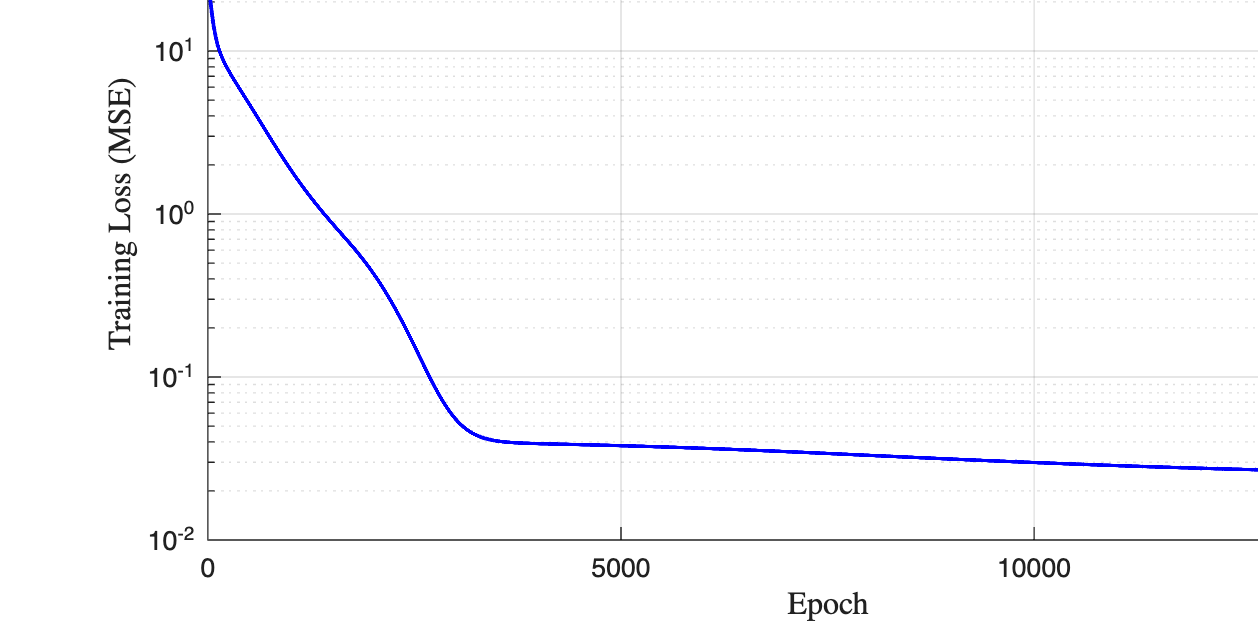

tic;
q_bar_pred_n = annForward(params, X_te);
q_bar_pred   = denorm_qb(double(extractdata(q_bar_pred_n)));

% reconstruct full solutions
w_test_ann = w_ref + V_prim * q_test + V_bar * q_bar_pred;
t_online_ann = toc;

% plot training loss
figure('Color','w','Position',[100 100 800 400]);
semilogy(1:n_epochs, loss_hist, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Epoch', 'Interpreter','latex', 'FontSize', 12);
ylabel('Training Loss (MSE)', 'Interpreter','latex', 'FontSize', 12);
title('ANN Training Loss', 'Interpreter','latex', 'FontSize', 13);

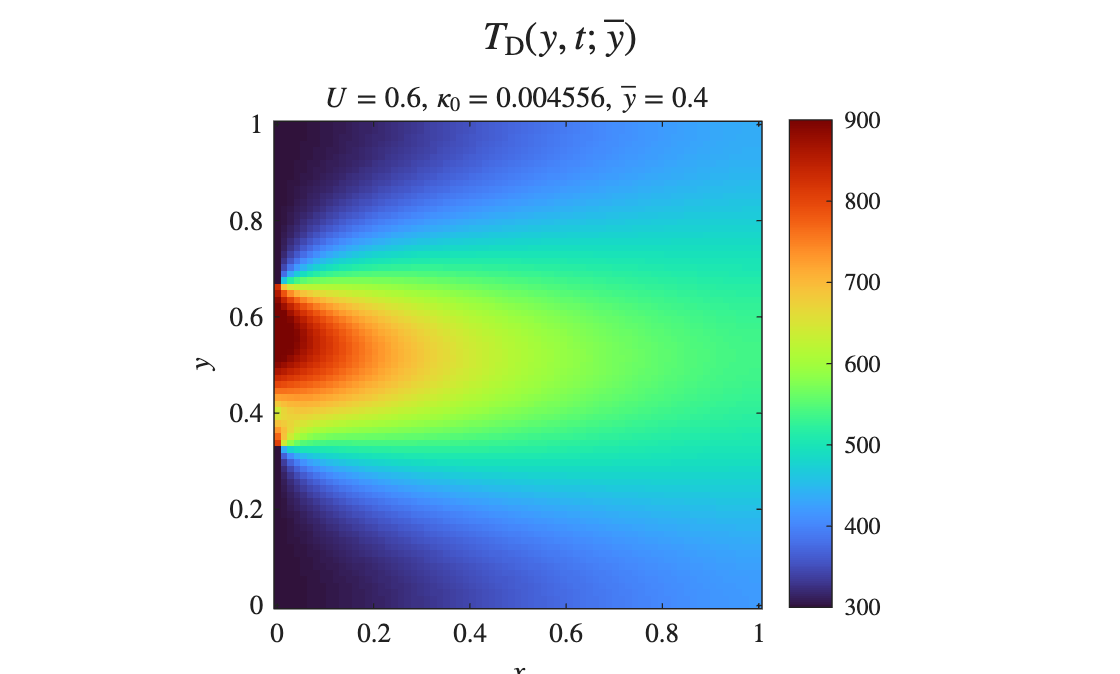


% vis one test case
j_vis   = 20;
T_hdm_v = reshapeSolution(w_test_ann_hdm(:,j_vis), Nx, Ny, T_D, y_values, mu_test_ann(j_vis,:));
T_ann_v = reshapeSolution(w_test_ann(:,j_vis),     Nx, Ny, T_D, y_values, mu_test_ann(j_vis,:));

plotSolution(T_hdm_v,            mu_test_ann(j_vis,:), false);

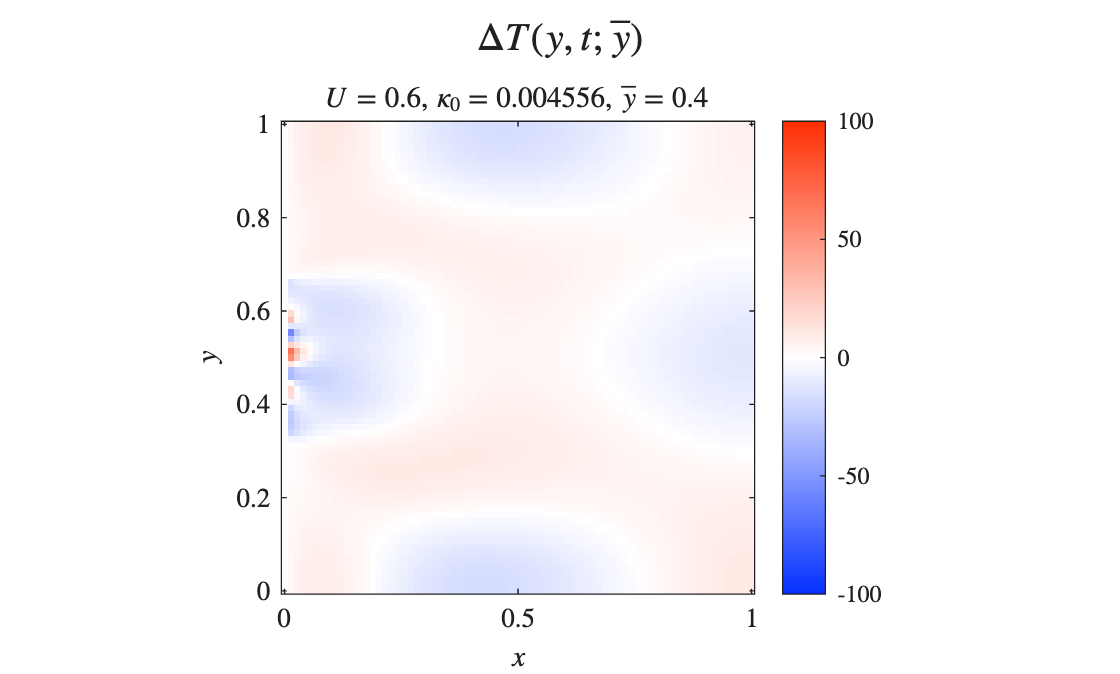

plotSolution(T_ann_v - T_hdm_v,  mu_test_ann(j_vis,:), true);

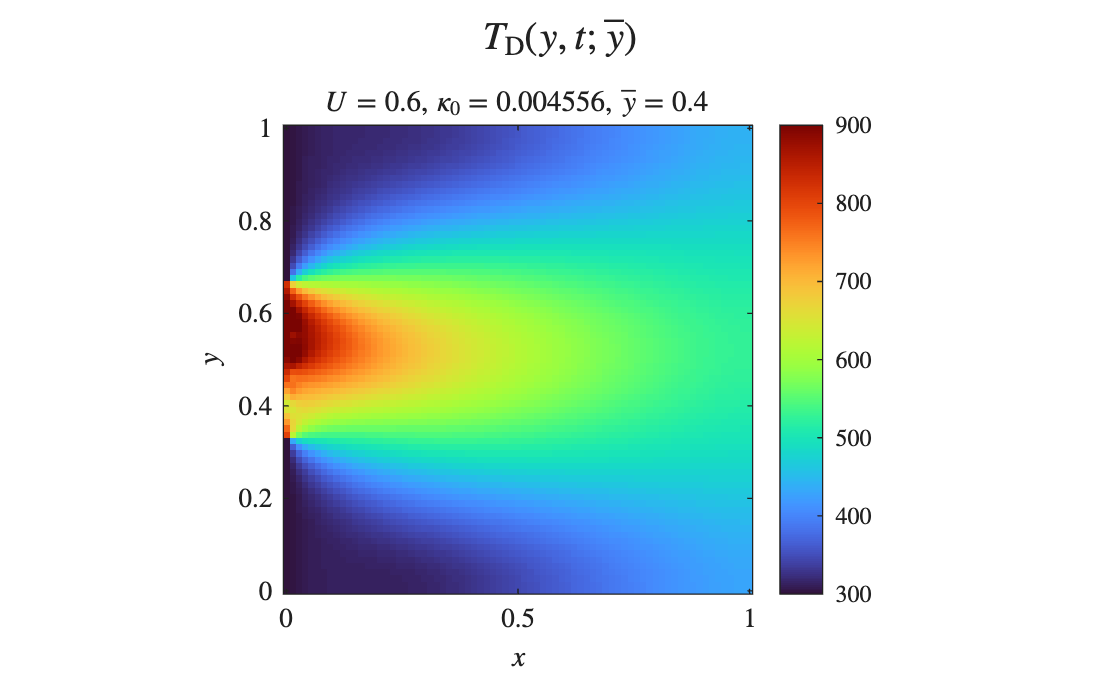

plotSolution(T_ann_v,            mu_test_ann(j_vis,:), false);

function q_bar_pred = annForward(params, X)
% forward pass:  linear -> tanh -> linear  +  quadratic skip
    Z1  = params.W1 * X + params.b1;        % h x N
    A1  = tanh(Z1);                          % h x N
    Z2  = params.W2 * A1 + params.b2;       % k_bar x N
    Xsq = X .* X;                            % quadratic skip: k x N
    q_bar_pred = Z2 + params.W3 * Xsq;      % k_bar x N
end

function [loss, grads] = annForwardLoss(params, X, Y, lambda_reg)
% MSE loss + L2 regularization
    Y_pred = annForward(params, X);
    N      = size(Y, 2);
    mse    = sum((Y_pred - Y).^2, 'all') / N;
    reg    = lambda_reg * (sum(params.W1.^2,'all') + ...
                           sum(params.W2.^2,'all') + ...
                           sum(params.W3.^2,'all'));
    loss   = mse + reg;
    grads  = dlgradient(loss, params);
end

## PROM Error Analysis

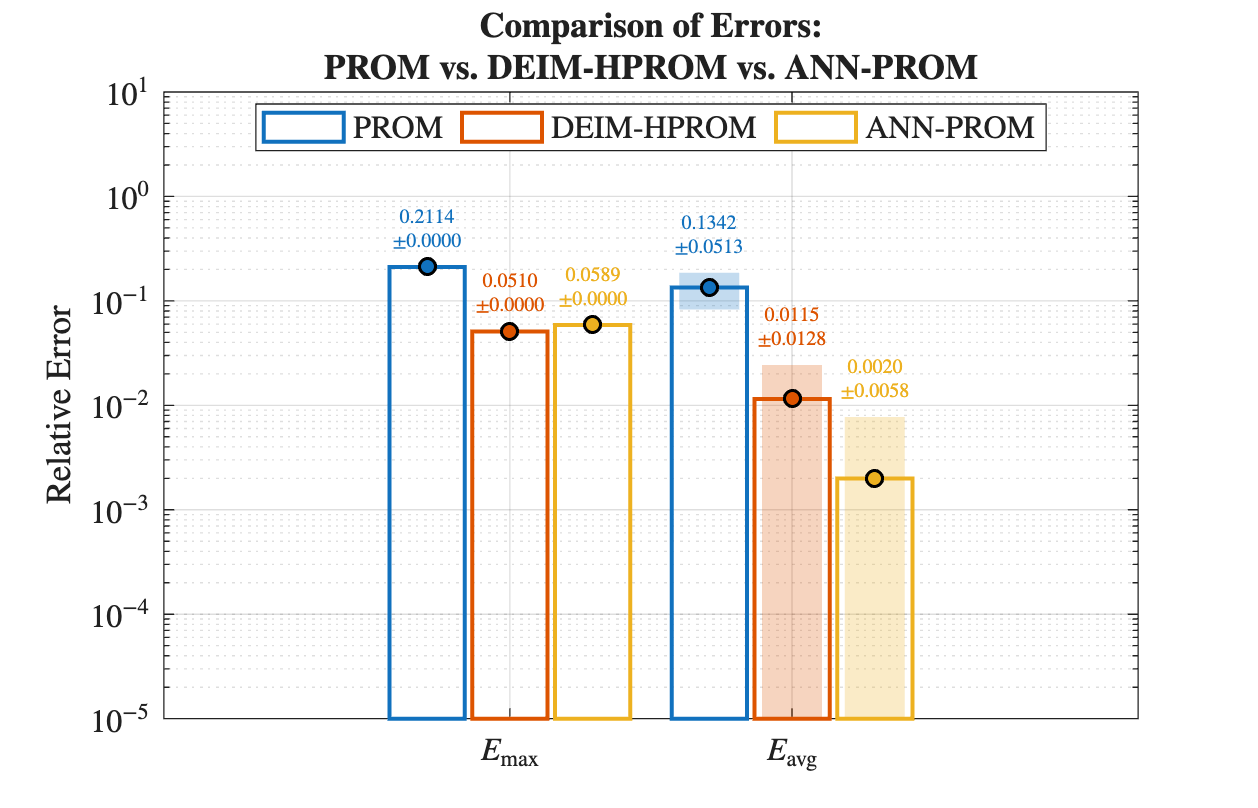

% STD Galerkin
errors_affine = computeErrors(w_test_k, w_r_k);
E_max_affine  = max(errors_affine);
E_avg_affine  = mean(errors_affine);
E_std_affine  = std(errors_affine);

% DEIM
errors_deim = computeErrors(w_test_deim, w_r_deim);
E_max_deim  = max(errors_deim);
E_avg_deim  = mean(errors_deim);
E_std_deim  = std(errors_deim);

% ANN
errors_ann = computeErrors(w_test_ann_hdm, w_test_ann);
E_max_ann  = max(errors_ann);
E_avg_ann  = mean(errors_ann);
E_std_ann  = std(errors_ann);

means = [E_max_affine,  E_max_deim,  E_max_ann;
         E_avg_affine,  E_avg_deim,  E_avg_ann];

stdevs = [0,             0,           0;
          E_std_affine,  E_std_deim,  E_std_ann];

plotErrorComparison(means, stdevs, {'PROM', 'DEIM-HPROM', 'ANN-PROM'}, true);

## PROM Computational Cost Analysis

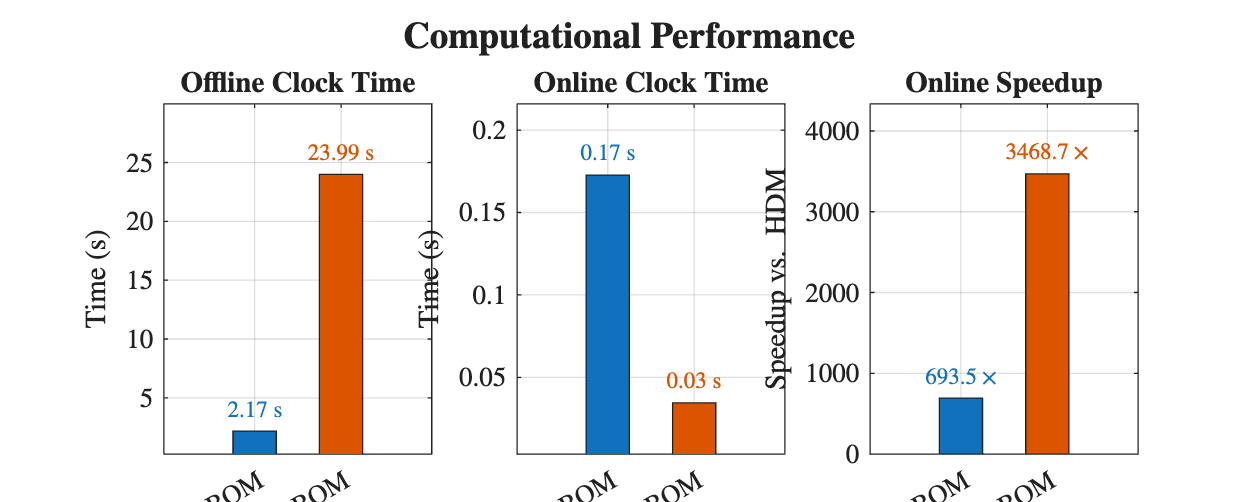

t_hdm_per = time_HDM / N_mu;
t_hdm_test = t_hdm_per * N_test;

speedup_deim = t_hdm_test / t_online_deim;
speedup_ann  = t_hdm_test / t_online_ann;

times_offline = [t_offline_deim, t_offline_ann];
times_online  = [t_online_deim,  t_online_ann];
speedups      = [speedup_deim,   speedup_ann];

plotTimeComparison(times_offline, times_online, speedups, ...
    {'DEIM-HPROM', 'ANN-PROM'});

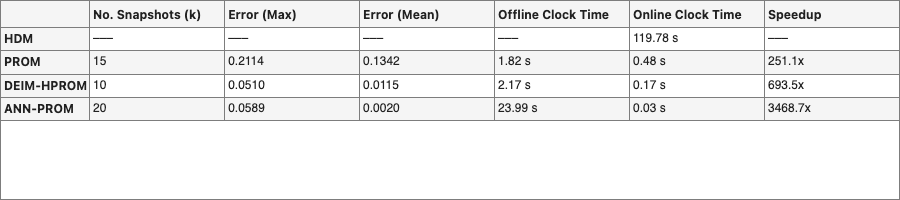

Method    = ["HDM"; ...
             sprintf("PROM"); ...
             sprintf("DEIM-HPROM"); ...
             sprintf("ANN-PROM")];

Snapshots = ["–––"; sprintf("%d", k_plateau); sprintf("%d", k_deim); sprintf("%d", k_ann)];
E_max_col = ["–––"; sprintf("%.4f", E_max_affine); sprintf("%.4f", E_max_deim); sprintf("%.4f", E_max_ann)];
E_avg_col = ["–––"; sprintf("%.4f", E_avg_affine); sprintf("%.4f", E_avg_deim); sprintf("%.4f", E_avg_ann)];
offline_s = ["–––"; sprintf("%.2f s", t_offline_affine); sprintf("%.2f s", t_offline_deim); sprintf("%.2f s", t_offline_ann)];
online_s  = [sprintf("%.2f s", t_hdm_test); sprintf("%.2f s", t_online_affine); sprintf("%.2f s", t_online_deim); sprintf("%.2f s", t_online_ann)];
speedup   = ["–––"; sprintf("%.1fx", t_hdm_test / t_online_affine); sprintf("%.1fx", speedup_deim); sprintf("%.1fx", speedup_ann)];

T = table(Snapshots, E_max_col, E_avg_col, offline_s, online_s, speedup, ...
    'RowNames',       cellstr(Method), ...
    'VariableNames',  {'No. Snapshots (k)','Error (Max)','Error (Mean)','Offline Clock Time','Online Clock Time','Speedup'});

fig = uifigure('Name', 'ROM Performance Summary', 'Position', [100 100 900 200]);
uitable(fig, 'Data', T, 'Units', 'Normalized', 'Position', [0 0 1 1]);